# Homework 8

Math 3607, Autumn 2021

Marco LoPiccolo

## Problem 1.

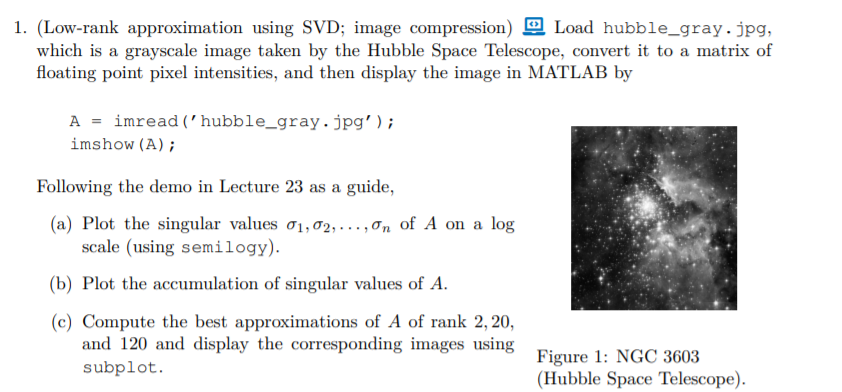

#### Part a.)

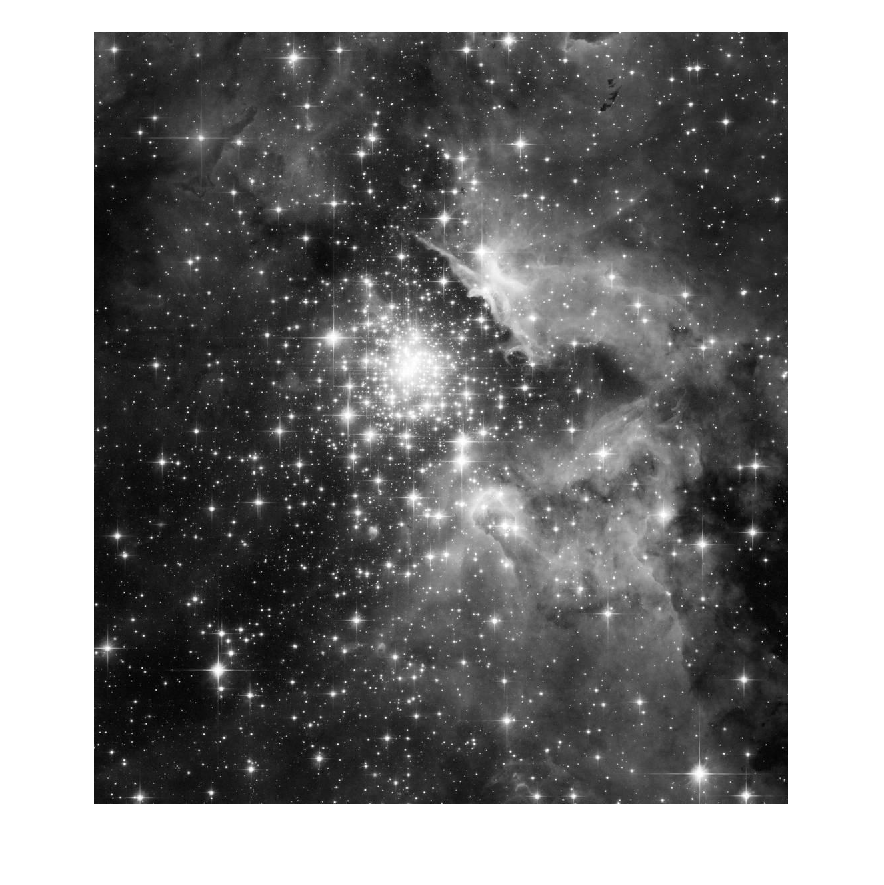

clf
load hubble_gray.jpg
A = imread('hubble_gray.jpg');
imshow(A);

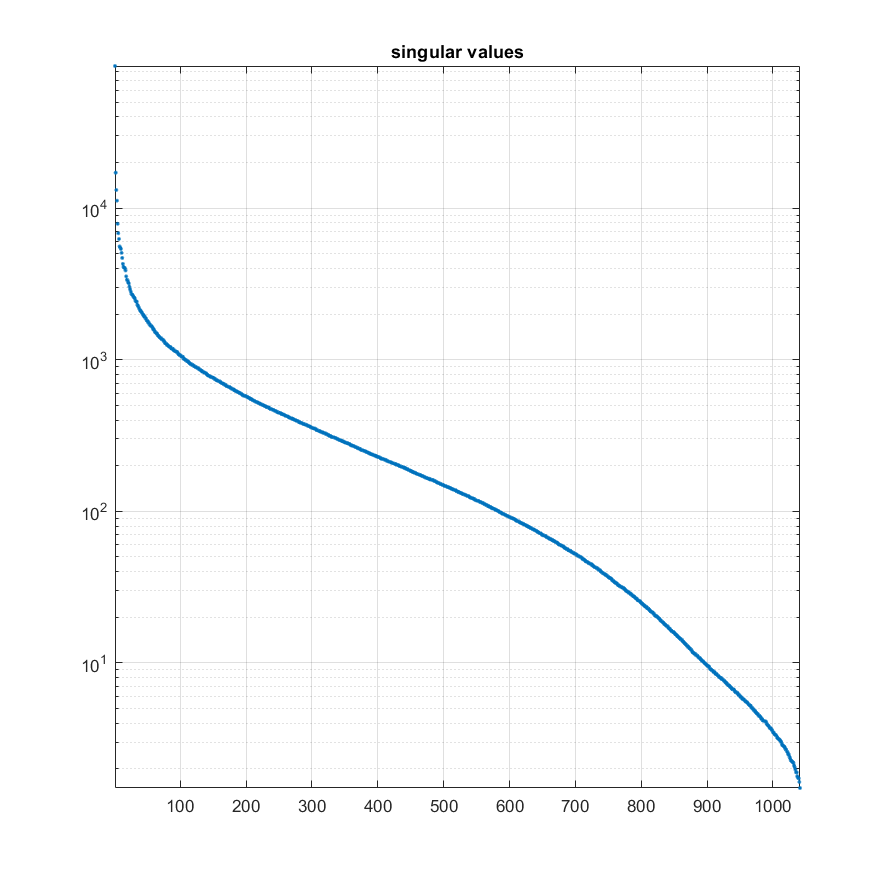

A = double(A);
[U,S,V] = svd(A);
sigma = diag(S);
clf
semilogy(1:length(sigma), sigma, '.')
title('singular values'), axis tight, grid on

#### Part b.)

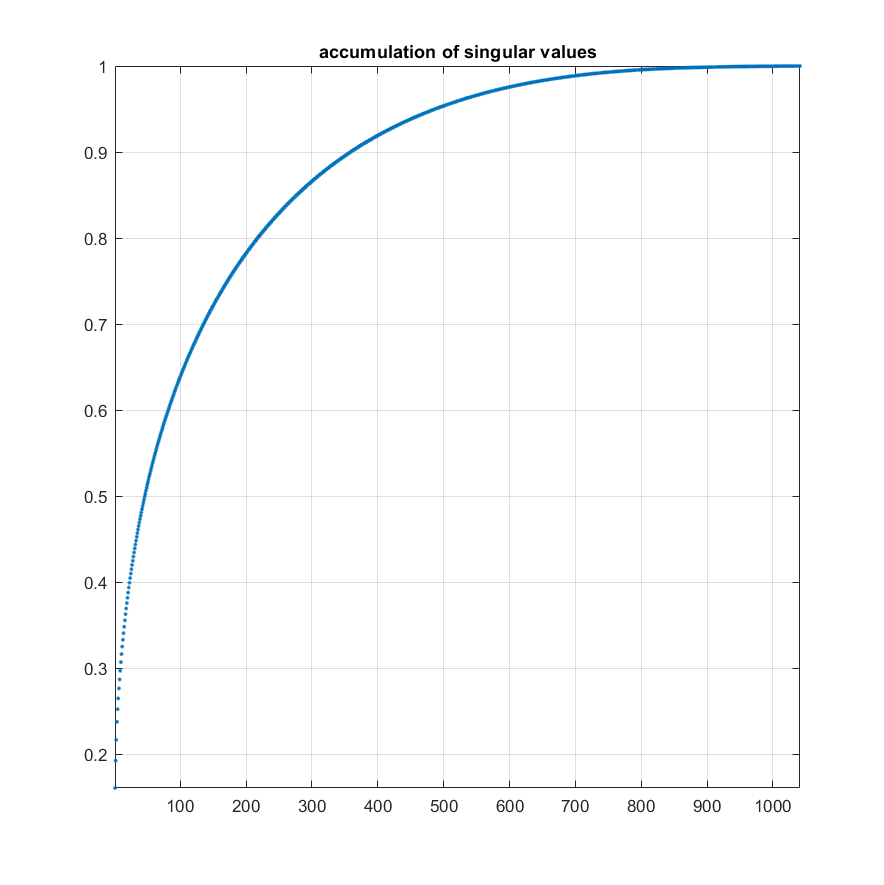

clf
plot(1:length(sigma), cumsum(sigma)/sum(sigma), '.')
title('accumulation of singular values'), axis tight, grid on 

#### Part c.)

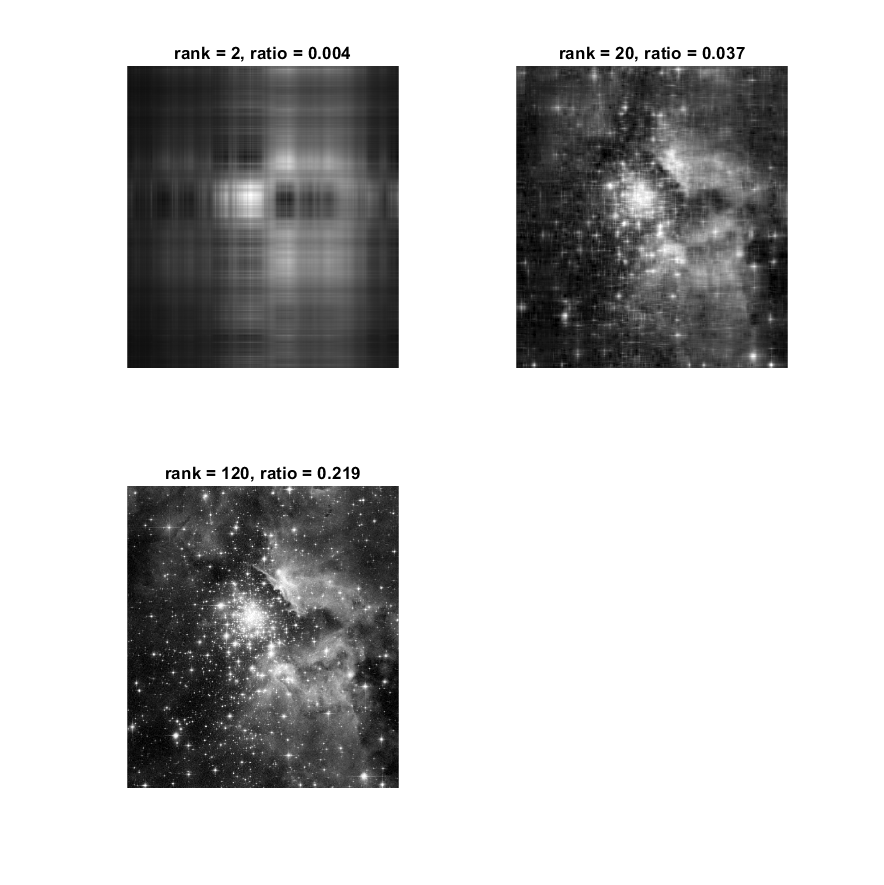

j = 0;
[m,n] = size(A);
clf
for k = [2 20 120]
    j = j + 1;
    subplot(2, 2, j)
    Ak = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';  % rank-k approximation
    imshow(Ak, [0, 255])
    comp_ratio = k*(m+n+1)/(m*n);
    title(sprintf('rank = %d, ratio = %5.3f', k, comp_ratio))  
end

## Problem 2.

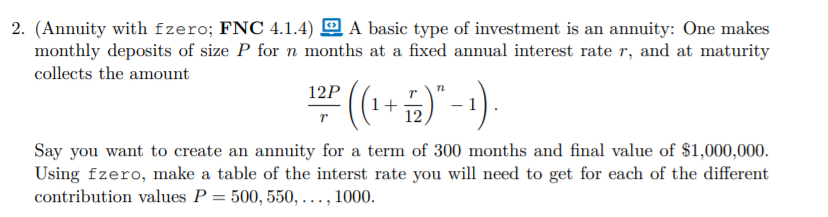

n = 300;
finalValue = 1000000;
f = @(r, P) (12*P/r) * ((1+(r/12))^n - 1) - finalValue;
P = 500:50:1000;
r = zeros(size(P));
for j = 1:length(P)
    r(j) = fzero(@(r) f(r, P(j)), 1);
end
%use relative error for all the values in r
relerr = zeros(size(P));
for j = 1:length(P)
    relerr(j) = f(r(j),P(j)) / finalValue;
end
format long g
fprintf('                    P               Interest Rate              Relative Error')

                    P               Interest Rate              Relative Error

fprintf('-----------------------------------------------------------------------------')

-----------------------------------------------------------------------------

disp([P', r', relerr'])

                       500         0.123511807047063      1.16415321826935e-14
                       550          0.11814632045792      1.93249434232712e-14
                       600         0.113200201561364     -2.15368345379829e-14
                       650          0.10860744853049     -2.94530764222145e-14
                       700         0.104316606191742      2.28174030780792e-14
                       750         0.100286770470683      1.50175765156746e-14
                       800        0.0964848788646416     -2.96859070658684e-14
                       850        0.0928838197313124      1.97906047105789e-14
                       900        0.0894610800540336     -9.77888703346252e-15
                       950        0.0861977573629547      3.00351530313492e-14
                      1000        0.0830778240105258      2.44472175836563e-14



## Problem 3. 

#### 

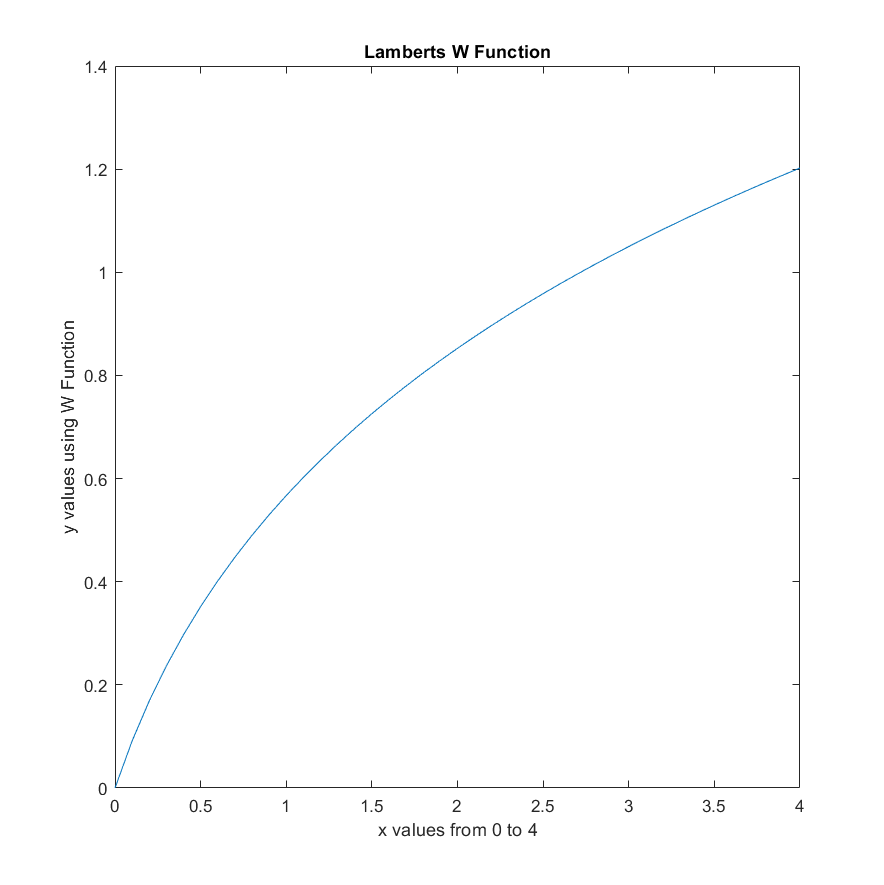

format long g
x = 0:0.1:4;
W = LambertW(x)';   %My function
K = lambertw(x)';   %Matlab's Built in Function to check
W - K;
clf
plot(x, W)
title('Lamberts W Function')
xlabel('x values from 0 to 4')
ylabel('y values using W Function')

## Problem 4. 

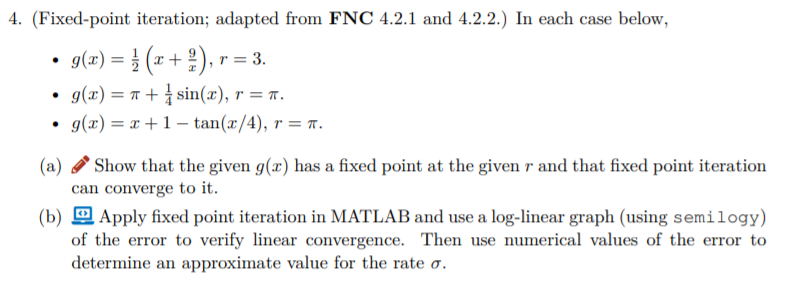

#### Part a.)

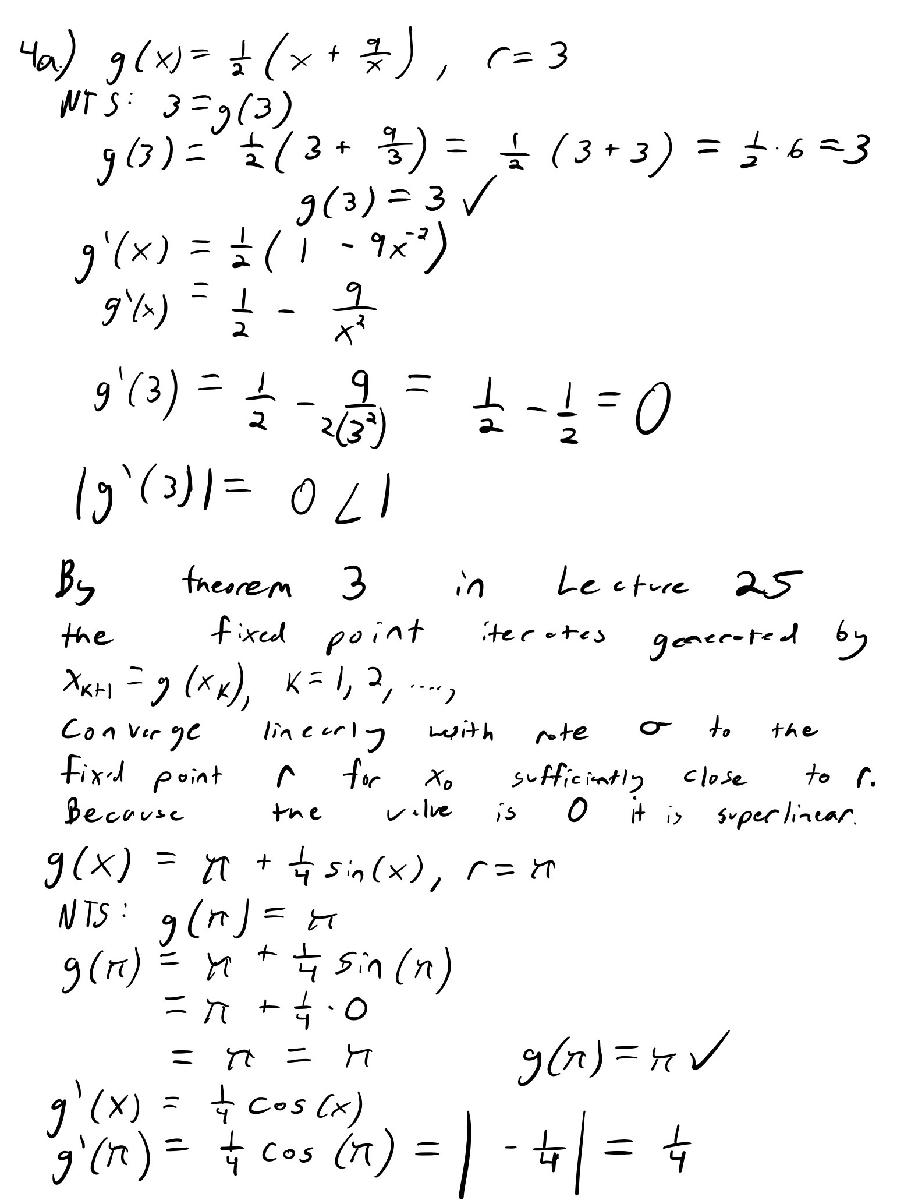

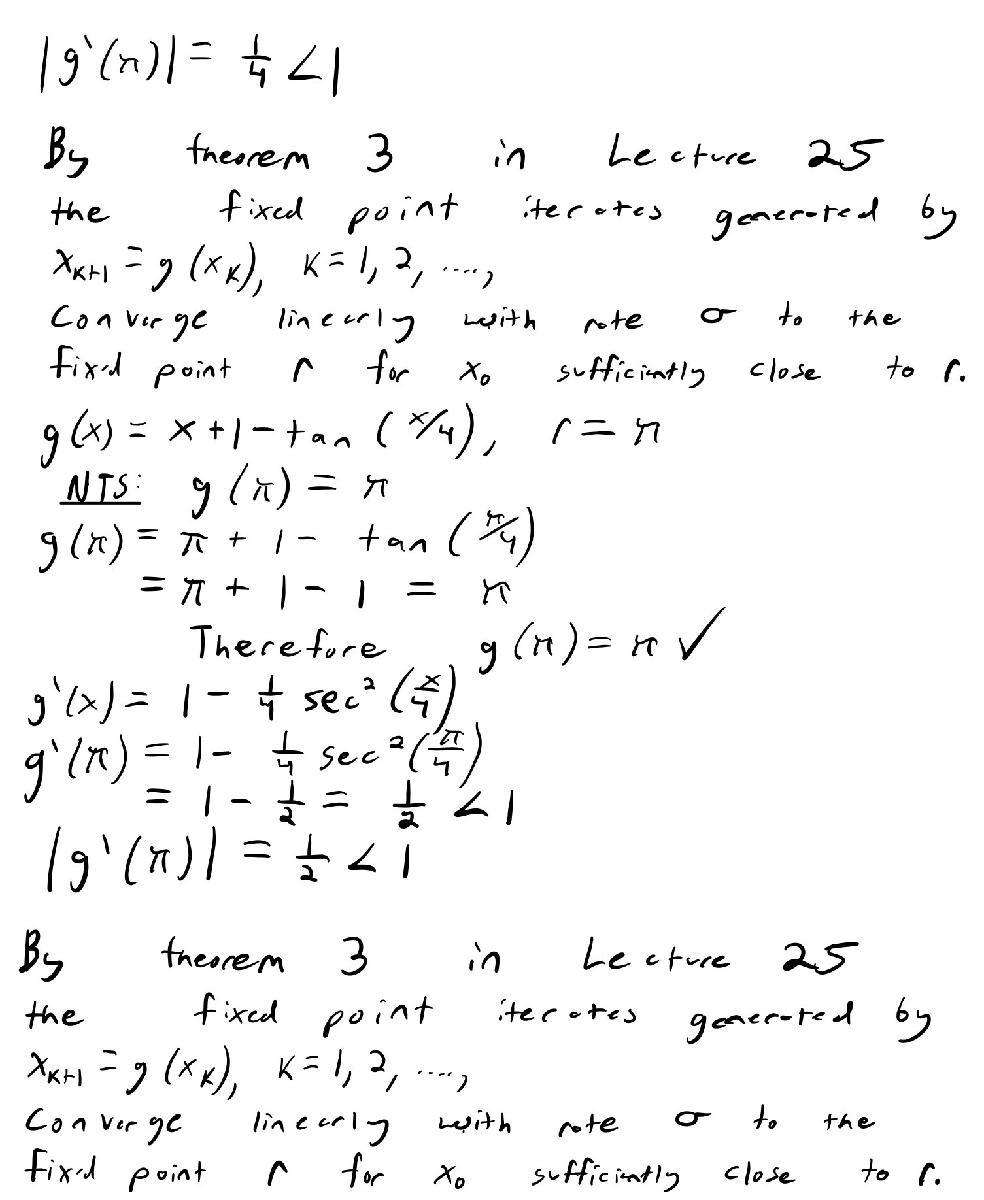

#### Part b.)

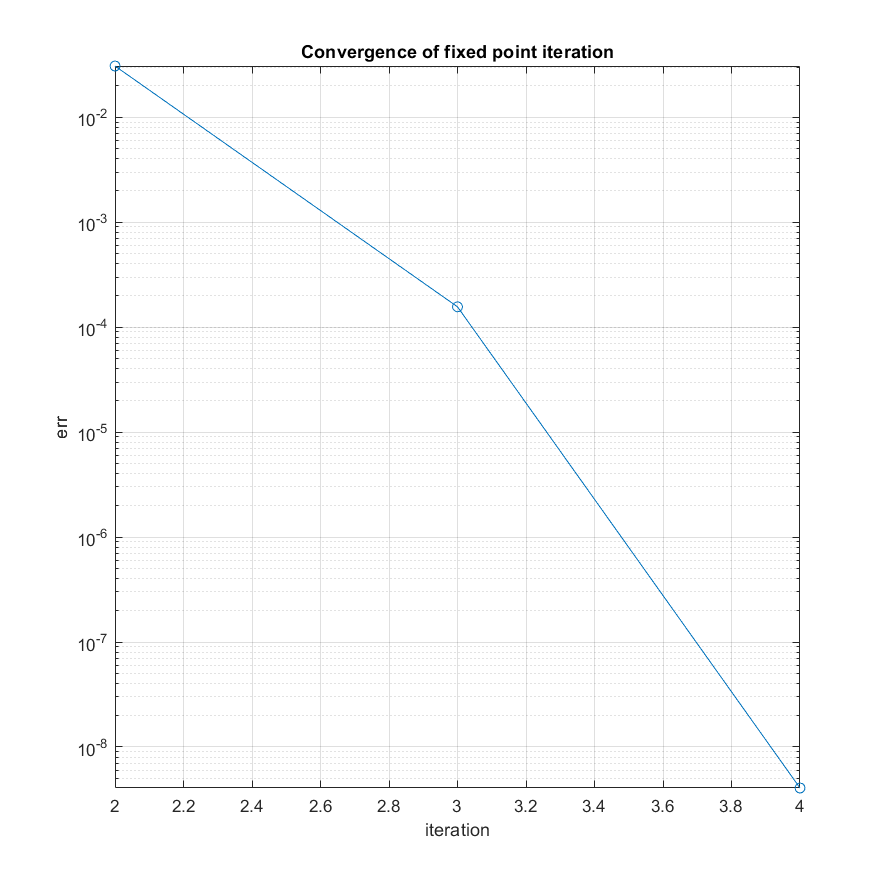

g = @(x) (1/2) * (x+(9/x));
n = 10;
x = zeros(n, 1);
err = zeros(n,1);
r = 3;
x(1) = 2.6;
for k = 1:n-1
    x(k+1) = g(x(k));     %FPI
    err(k+1) = abs(x(k+1) - r);
end
clf
semilogy(1:10, err, 'o-')
xlabel('iteration')
ylabel('err')
title('Convergence of fixed point iteration')
axis tight, grid on

%The iteration converges very fast and the errors after the fourth are just
%zeros and becomes invisible to semilogy which is evident in the fact that
%the analytical calculation is super linear convergence as it is 0
%This is means that our sigma will also have to start at a lower value to
%ensure that we do not have a 0/0 when approximating the value
ApproximateValue = err(3:5)./err(2:4)

ApproximateValue =        0.00507614213198006
      2.60301424037639e-05
                         0


%We keep it below 5 to ensure no 0/0 calculations but based off of the
%values the approximate error appears to be going towards zero which based
%on the analytical calculations done above we can confirm that this is
%approximately estimating the rate sigma

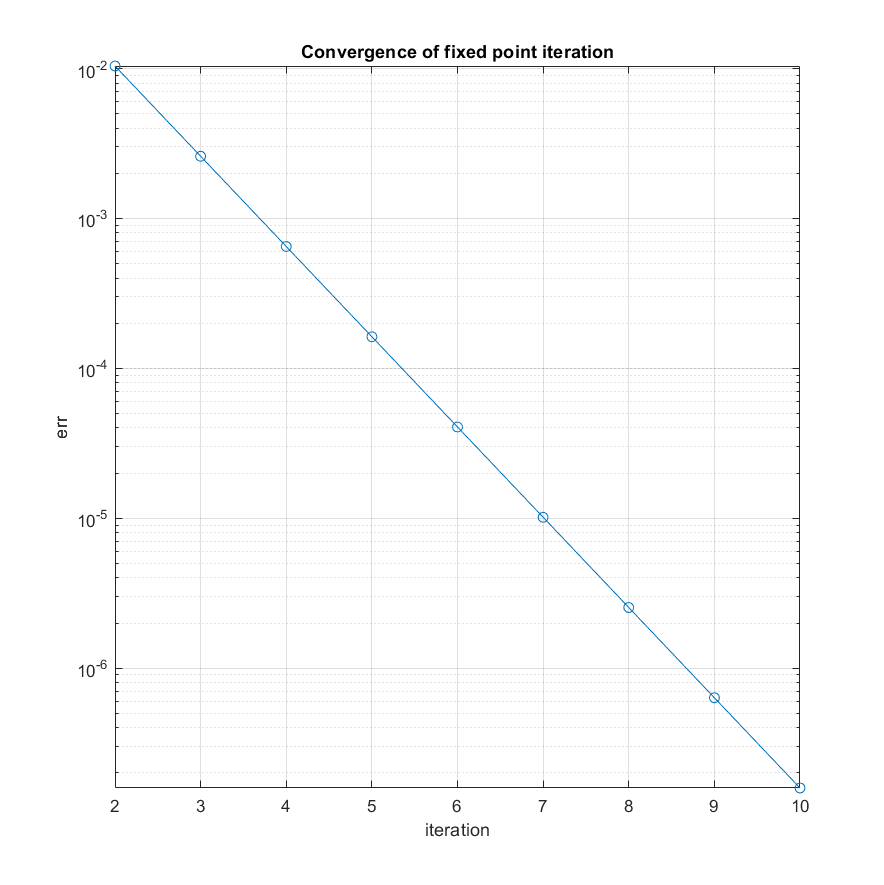

h = @(x) pi + (1/4)*sin(x);
n = 10;
x = zeros(n, 1);
err = zeros(n,1);
r = pi;
x(1) = 3.1;
for k = 1:n-1
    x(k+1) = h(x(k));     %FPI
    err(k+1) = abs(x(k+1) - r);
end
clf
semilogy(err, 'o-')
xlabel('iteration')
ylabel('err')
title('Convergence of fixed point iteration')
axis tight, grid on

ApproximateValue = err(4:10) ./ err(3:9)

ApproximateValue =           0.24999971860531
         0.249999982413071
         0.249999998901543
          0.24999999993438
                      0.25
         0.249999999912506
                      0.25


%Based on our analytical calculations above we should see the approximate
%rate to be close to 1/4 which based on the error approximations we see
%here that is confirmed as all the values appear to be right around 1/4
%with a few discrepancies here and there

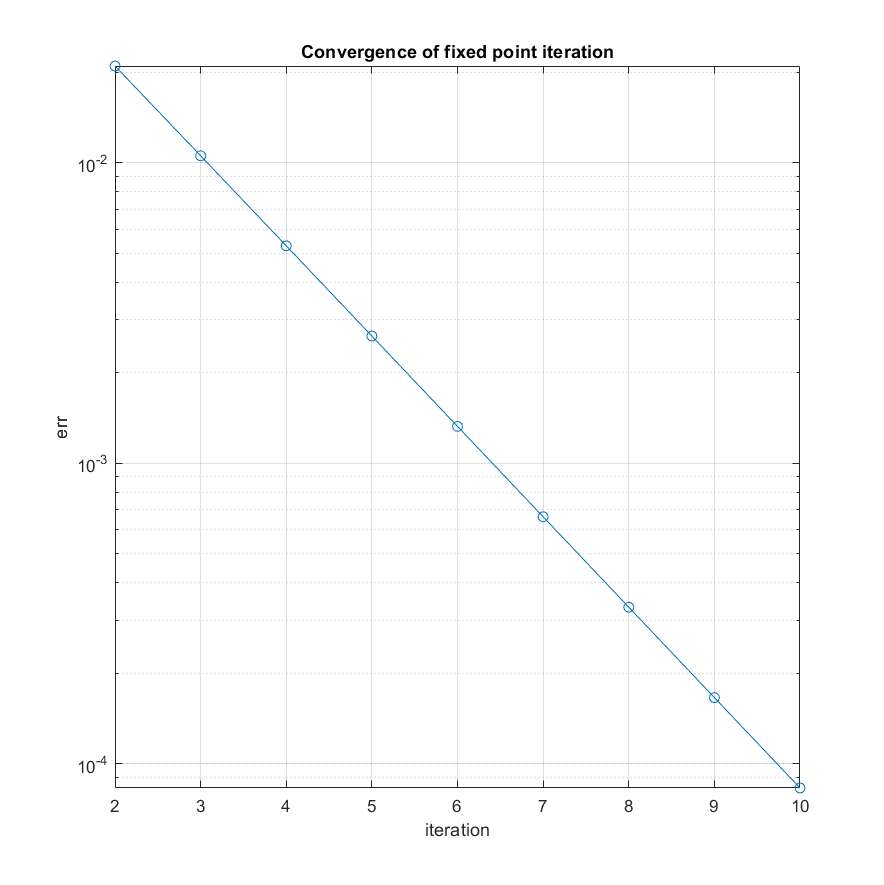

i = @(x) x + 1 - tan(x/4);
n = 10;
x = zeros(n, 1);
err = zeros(n,1);
r = pi;
x(1) = 3.1;
for k = 1:n-1
    x(k+1) = i(x(k));     %FPI
    err(k+1) = abs(x(k+1) - r);
end
clf
semilogy(err, 'o-')
xlabel('iteration')
ylabel('err')
title('Convergence of fixed point iteration')
axis tight, grid on

ApproximateValue = err(4:10) ./ err(3:9)

ApproximateValue =          0.501315318857684
         0.500660545264199
         0.500331000135971
         0.500165682707762
           0.5000828871099
         0.500041455004945
         0.500020730367182


%Based on the analytical calculation above we should see the approximate
%rate to be close to 1/2 which in our error calculations we do see that to
%be the case with many of the values being very close to 1/2 with only a
%few discrepancies here and there

## Problem 5. 

#### 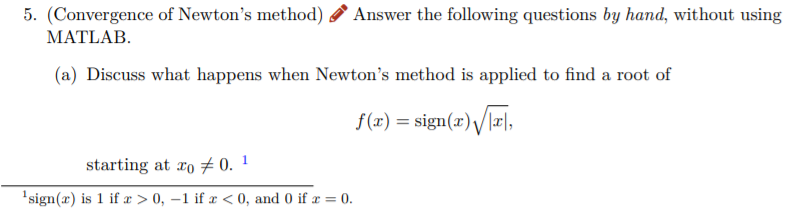

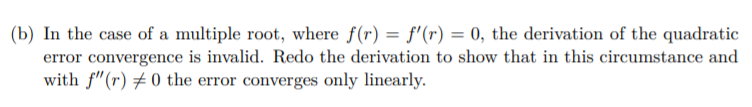

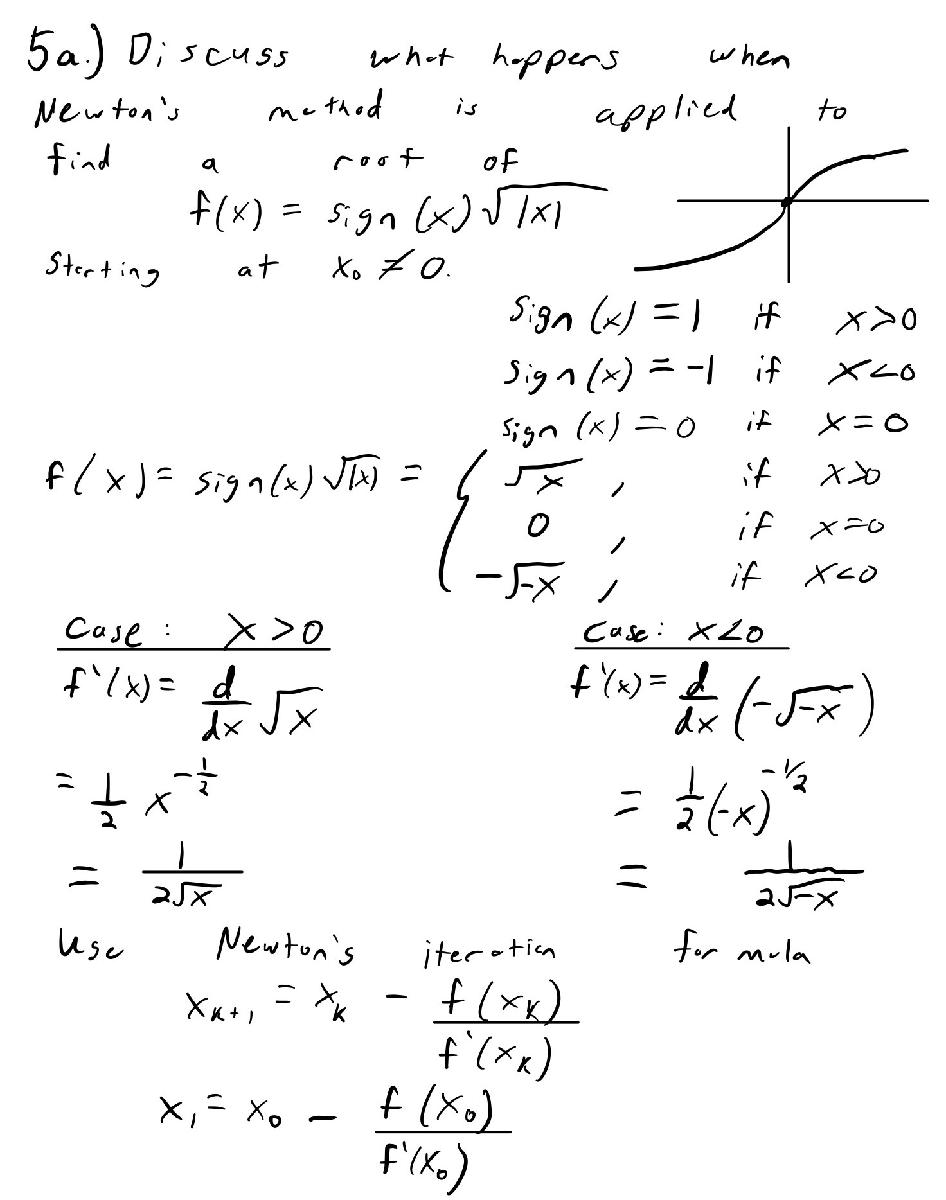

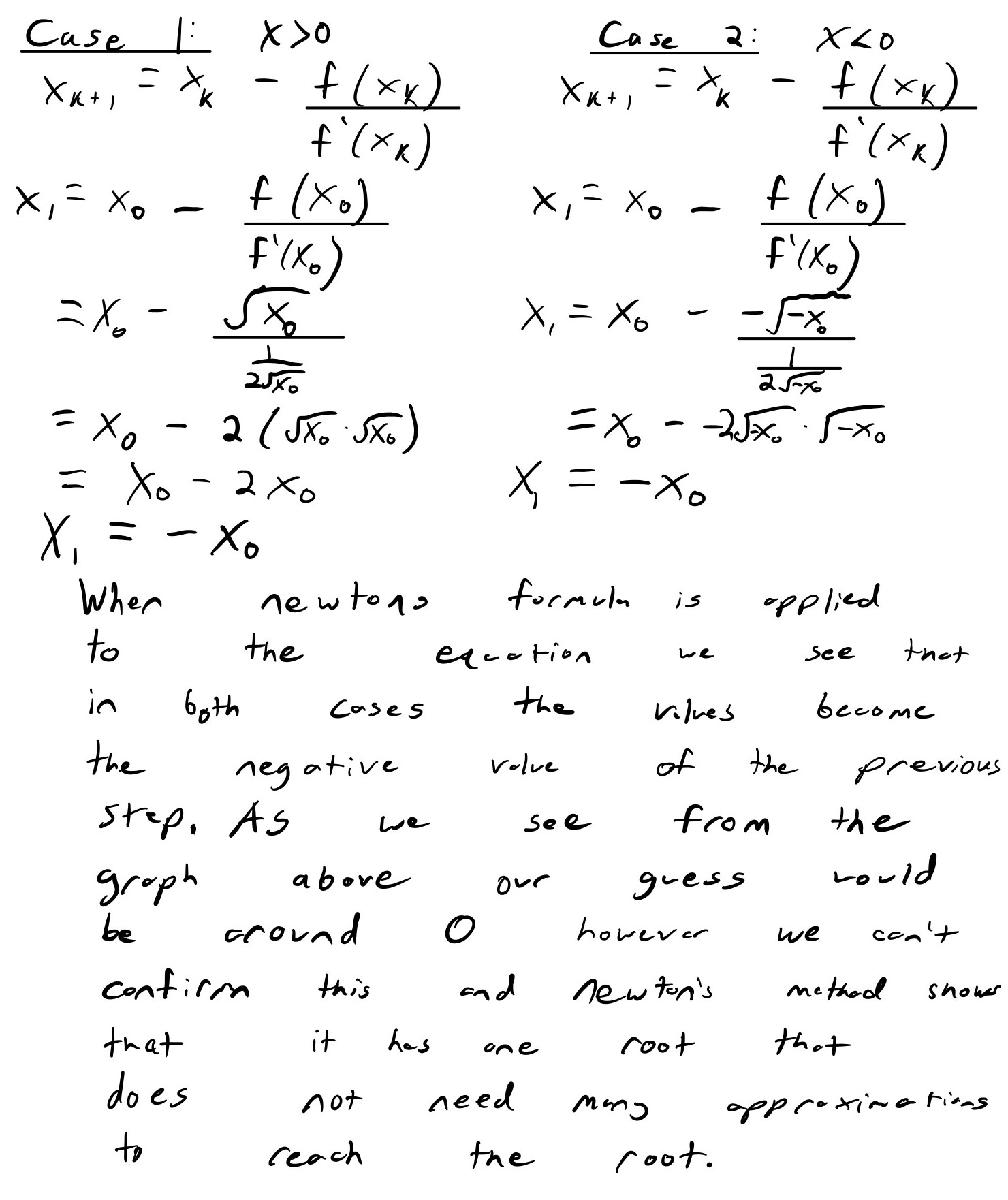

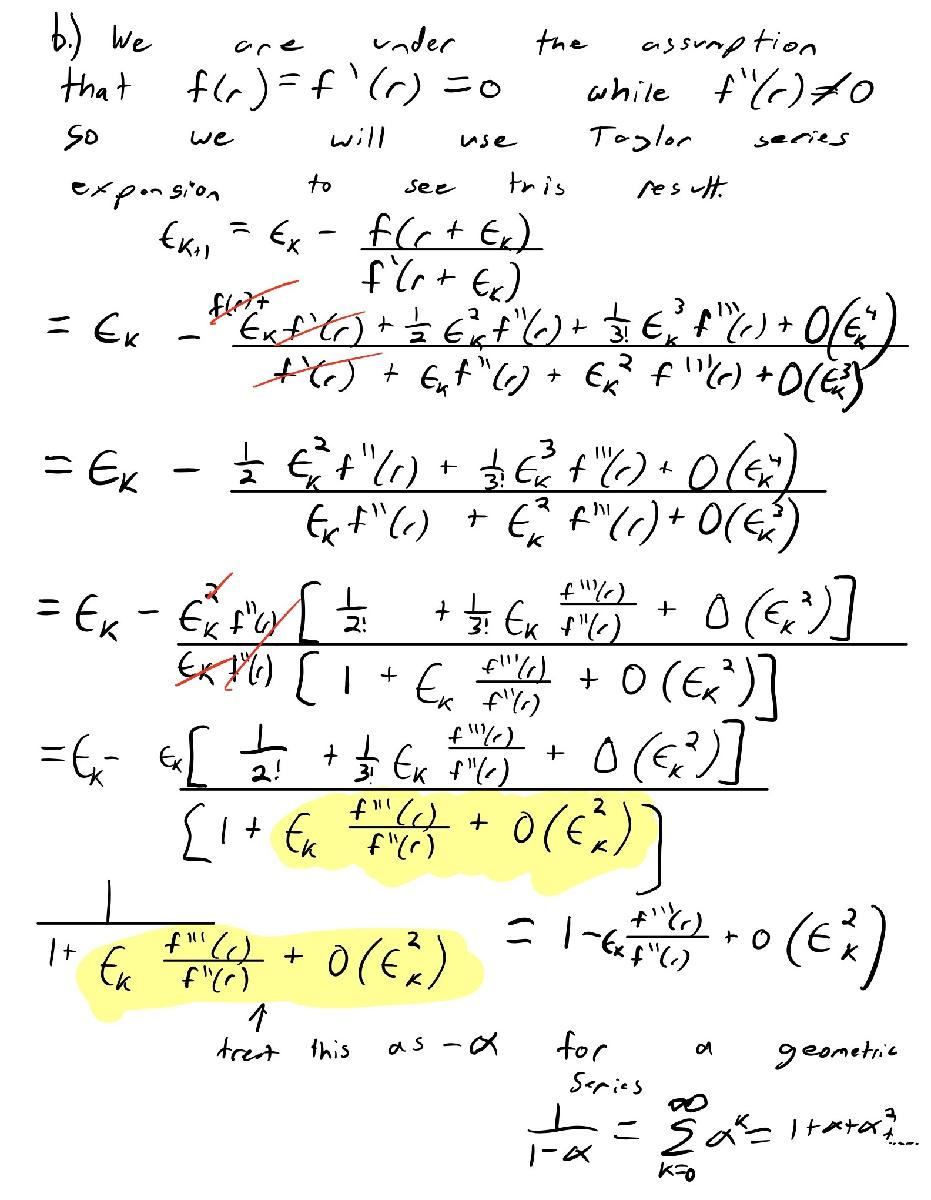

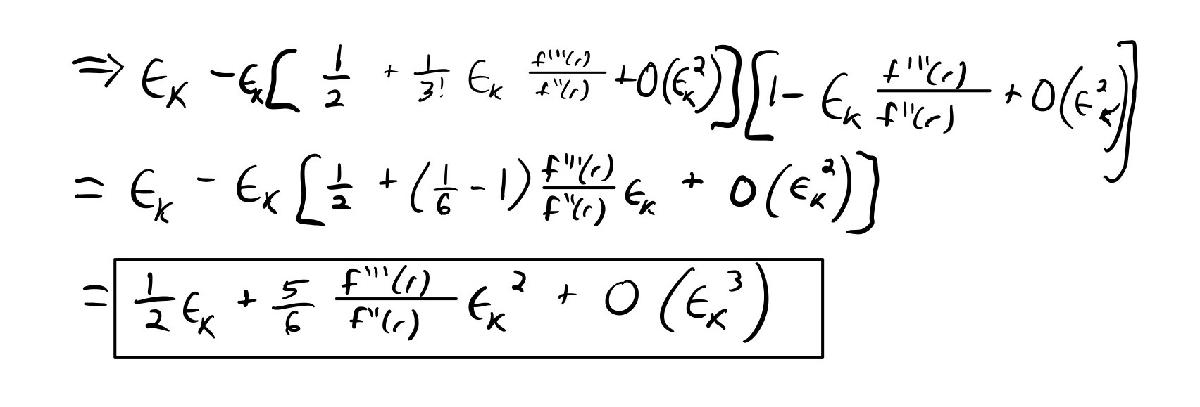

## Function Lambert's W Function

function y = LambertW(x)
% Function Lambert W Function
% Calculates the inverse of inputted x vector to solve for another vector
% y
f = @(x,y) x - y*exp(y);
y = zeros(size(x));
for j = 1:length(x)
    y(j) = fzero(@(y) f(x(j), y), (-1 + sqrt(1 + 4*x(j)))/2 );
end
end